%
% Conversion of Random Uniform Variables to Random Gaussian Variables
%


close all
clear all

%
% method 1: LUT: piecewise constant approximation on uniform interval
%

ds    = 8:2:16;  %8:2:16
errs1 = [];
fprintf('Method 1: Piecewise constant approximation on uniform intervals')

Method 1: Piecewise constant approximation on uniform intervals


for d = ds
  k  = 1:2^(d-1);
  du = 2^(-d);
  Z_ave  = norminv_int((k-1)*du,k*du)/du;
  Z2_ave = norminv2_int((k-1)*du,k*du)/du;

  err   = 2*du*sum(Z2_ave-Z_ave.^2);
  errs1 = [errs1 err];

  fprintf(1,'method 1: d = %2d, err = %f \n',d,err)
end

method 1: d =  8, err = 0.000743 
method 1: d = 10, err = 0.000150 
method 1: d = 12, err = 0.000031 
method 1: d = 14, err = 0.000007 
method 1: d = 16, err = 0.000001 



%
% method 2: piecewise constant approximation on dyadic interval
%

errs2 = [];

fprintf('Method 2: Piecewise linear approximation on dyadic intervals')

Method 2: Piecewise linear approximation on dyadic intervals

for d = ds
  du = 2^(-d);
  k  = 1:2^(d-1);
  Z_ave  = norminv_int((k-1)*du,k*du)/du;
  Z2_ave = norminv2_int((k-1)*du,k*du)/du;

  err = 0;

  for k = 1:d-1
    if k==1 
      u_min = 0;
      n_sub = 2;
      k2 = 1:2;
    else
      u_min = 2^(k-d-1);
      n_sub = 2^(k-1);
      k2 = (n_sub+1):2*n_sub;
    end
    u_max = 2^(k-d);

    Z_ave2 = sum(Z_ave(k2))/n_sub;
    dn = (1:n_sub) - (n_sub+1)/2;
    dZ = Z_ave(k2) - Z_ave2;
    dZ = (dZ*dn') / (dn*dn');

    Z2(k2) = Z_ave2 + dn*dZ;

    err = err + 2*du*(sum(Z2_ave(k2)-Z_ave(k2).^2+(Z2(k2)-Z_ave(k2)).^2));
  end

  errs2 = [errs2 err];
  fprintf(1,'method 2: d = %2d, err = %f \n',d,err)
end

method 2: d =  8, err = 0.000783 
method 2: d = 10, err = 0.000191 
method 2: d = 12, err = 0.000073 
method 2: d = 14, err = 0.000048 
method 2: d = 16, err = 0.000043 



%
% method 3: piecewise constant approximation on super-dyadic interval
% (instead of successive intervals of 2 like the dyadic, we now use
% \sqrt(2)
%
errs3 = [];
fprintf('Method 3: Piecewise linear approximation on syper-dyadic intervals')

Method 3: Piecewise linear approximation on syper-dyadic intervals


for d = ds
    du = 2^(-d);
    N = 2^(d-1);
    k = 1:N;
    Z_ave  = norminv_int((k-1)*du, k*du) / du;
    Z2_ave = norminv2_int((k-1)*du, k*du) / du;

    err = 0;
    idx = 1;
    Z2 = zeros(1, N);

    n_subs = [];
    total = 0;
    lvl = 1;
    while total < N
        n_this = 2^floor((lvl-1)/2);
        if total + n_this > N
            n_this = N - total;
        end
        n_subs = [n_subs, n_this];
        total = total + n_this;
        lvl = lvl + 1;
    end

    idx = 1;
    for k_lvl = 1:length(n_subs)
        n_sub = n_subs(k_lvl);
        k2 = idx:(idx + n_sub - 1);

        Z_ave2 = mean(Z_ave(k2));
        dn = (1:n_sub) - (n_sub+1)/2;
        dZ = Z_ave(k2) - Z_ave2;
        if sum(dn.^2) == 0
            dZslope = 0;
        else
            dZslope = (dZ * dn') / (dn * dn');
        end

        Z2(k2) = Z_ave2 + dn * dZslope;

        err = err + 2 * du * sum(Z2_ave(k2) - Z_ave(k2).^2 + (Z2(k2) - Z_ave(k2)).^2);

        idx = idx + n_sub;
    end

    errs3 = [errs3 err];
    fprintf(1, 'method 3 (super-dyadic): d = %2d, err = %f \n', d, err)
end

method 3 (super-dyadic): d =  8, err = 0.000747 
method 3 (super-dyadic): d = 10, err = 0.000153 
method 3 (super-dyadic): d = 12, err = 0.000035 
method 3 (super-dyadic): d = 14, err = 0.000010 
method 3 (super-dyadic): d = 16, err = 0.000005 


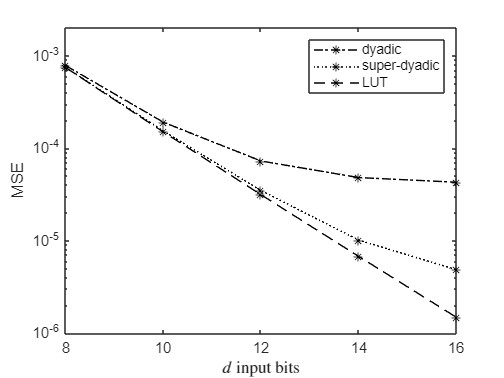





%
% plot final results for Figure 1 in the paper
%

figure; pos=get(gcf,'pos'); pos(3:4)=pos(3:4).*[0.8 0.8]; set(gcf,'pos',pos);

set(0,'DefaultAxesColorOrder',[0 0 0]);
set(0,'DefaultAxesLineStyleOrder','-.*|:*|--*|-*') 


semilogy(ds,errs2, ds,errs3, ds,errs1)
xlabel('$d$ input bits','Interpreter','latex') 
ylabel('MSE') 
legend('dyadic', 'super-dyadic', 'LUT')
axis([8 16 1e-6 2e-3])

print('-deps2','fig1.eps')


%
% also print out tabular information
%

fprintf("MSE for each method")

MSE for each method



fprintf(1,'\nbits       dyadic     super-dyadic       uniform \n')


bits       dyadic     super-dyadic       uniform 


for n = 1:length(ds)
  fprintf(1,' %2d   %12.7f  %12.7f  %12.7f \n', ...
	    ds(n), errs2(n), errs3(n), errs1(n))
end

  8      0.0007828     0.0007471     0.0007432 
 10      0.0001907     0.0001533     0.0001497 
 12      0.0000726     0.0000348     0.0000313 
 14      0.0000481     0.0000101     0.0000067 
 16      0.0000428     0.0000048     0.0000015 




%
% LUT Size (parameters)
%
fprintf("LUT Size (parameters)")

LUT Size (parameters)


N_LUT = 2.^(ds-1);        % LUT (piecewise constant)
N_dyadic = 2*(ds-1);      % Dyadic
N_super = 4*(ds-1);       % Super-dyadic

fprintf('\n%-5s %-12s %-12s %-12s\n', ...
    'bits','dyadic','super-dyadic','uniform');


bits  dyadic       super-dyadic uniform     


for n = 1:length(ds)
    fprintf('%-5d %-12d %-12d %-12d\n', ...
        ds(n), N_dyadic(n), N_super(n), N_LUT(n));
end

8     14           28           128         
10    18           36           512         
12    22           44           2048        
14    26           52           8192        
16    30           60           32768       


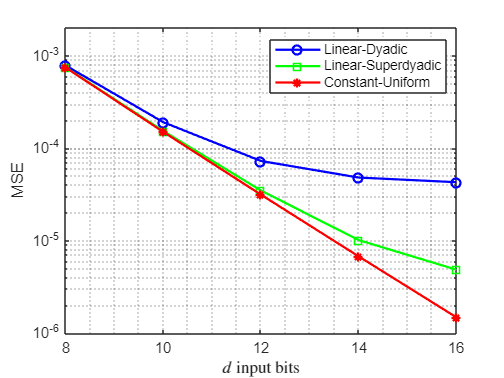



function y = norminv_int(u1,u2)
  u1 = max(u1,1e-15);
  u2 = min(u2,1-1e-15);
  z1 = norminv(u1);
  z2 = norminv(u2);
  y  = normpdf(z1)-normpdf(z2);
end

%
% this computes the integral of (Phi^{-1}(u))^2 over the interval [u1,u2]
%


%%%% Coloured Plot
figure; pos = get(gcf,'pos'); pos(3:4) = pos(3:4) .* [0.8 0.8]; set(gcf,'pos',pos);

semilogy(ds, errs2, 'b-o', 'LineWidth',1.5); hold on   % dyadic → blue
semilogy(ds, errs3, 'g-s', 'LineWidth',1.5);           % super-dyadic → green
semilogy(ds, errs1, 'r-*', 'LineWidth',1.5);           % constant → red

grid minor
xlabel('$d$ input bits','Interpreter','latex') 
ylabel('MSE') 
legend('Linear-Dyadic', 'Linear-Superdyadic', 'Constant-Uniform', 'Location', 'best')
axis([8 16 1e-6 2e-3])




%
% also print out tabular information
%



function y = norminv2_int(u1,u2)
  u1 = max(u1,1e-15);
  u2 = min(u2,1-1e-15);
  z1 = norminv(u1);
  z2 = norminv(u2);
  y  = z1.*normpdf(z1)-z2.*normpdf(z2)+(u2-u1);
end


